# F-16A Level 2 Sizing Analysis — Class-Based Example

This live script performs a Fidelity Level 2 sizing pass for the F-16A example using the toolkit classes supplied with the project. This version captures the W_TO value returned by SizingClassLevel2.size_aircraft().

Main objects used: * AircraftDesign * GeometryLevel2 * AeroLevel2 * PropulsionLevel2 * WeightLevel2 * MissionAnalysisLevel2 * ConstraintAnalysisClass * Requirements * SizingClassLevel2

The script assumes the corresponding class files, import utilities, design workbook, requirements table, constraints table, and mission profile are on the MATLAB path.

clear; close all;

## Project setup

Set this to the folder containing your classes, import utilities, design spreadsheet/workbook, requirements file, constraints file, and mission data.

projectRoot = pwd;
addpath(projectRoot);

% Change these names only if your local files use different names.
designName       = "F-16A Block 50";
requirementsName = "Requirements";
constraintsName  = "Constraints";
missionName      = "CAP";

## Create the aircraft design object

AircraftDesign is the project-level object. It imports the design geometry, fuselage data, propulsion data, weight data, general aircraft data, and requirements reference.

design = AircraftDesign( ...
    designName, ...
    RequirementsName = requirementsName, ...
    ConstraintsName  = constraintsName, ...
    AutoLoad         = true);

## Build the Level 2 analysis objects

Level 2 uses more design geometry than Level 1. GeometryLevel2 computes component wetted areas from exposed planform/body estimates, AeroLevel2 uses equivalent skin-friction and wetted-area buildup for CD0, PropulsionLevel2 estimates installed TSFC from Mach/altitude/engine type, and WeightLevel2 uses a more parameterized empty-weight regression.

geometry_obj     = GeometryLevel2(design);
aero_obj         = AeroLevel2();
propulsion_obj   = PropulsionLevel2(design);
weight_obj       = WeightLevel2(design);
mission_obj      = MissionAnalysisLevel2(missionName);
constraint_obj   = ConstraintAnalysisClass(design);

requirements_obj = Requirements(design);
sizing_obj       = SizingClassLevel2();

aero_obj.get_Cf(0.0035); % Initializing Cf manually because it's tabulated.

## Initialize constraints

We require constraints like "optimum wing-loading" and "minimum T/W" for sizing computations. So we'll initialize them, here.

constraint_obj.constraint_analysis % Requires zero arguments since it pulls from the constraint table.

% constraint_obj.show_constraints %% Optional; remove at leisure

## Run the project sizing class

This calls your SizingClassLevel3 method directly and captures the returned takeoff gross weight. The sizing class still displays its internal iteration table. A persistent trace is reconstructed in the next section for plots and reporting.

W_TO_fromSizingClass = sizing_obj.size_aircraft( ...
    design, ...
    geometry_obj, ...
    mission_obj, ...
    weight_obj, ...
    propulsion_obj, ...
    constraint_obj, ...
    requirements_obj, ...
    aero_obj);

     WTO     W_fixed    Fuel_fraction    Empty_weight_fraction    Empty_weight    WTO_new    Difference    Percent_Diff
    _____    _______    _____________    _____________________    ____________    _______    __________    ____________
    45000     5100         0.23782              0.56961              25632         40829       -4171.5           -9.27 
    40829     5100         0.23783              0.57537              23492         37752       -3076.1         -7.5341 
    37752     5100         0.23781              0.58006              21899         35468       -2284.3         -6.0508 
    35468     5100         0.23776              0.58381              20707         33762       -1705.9         -4.8098 
    3376


fprintf("\nSizingClassLevel2 returned W_TO = %.3f lbf.\n", W_TO_fromSizingClass);


SizingClassLevel2 returned W_TO = 28505.383 lbf.


fprintf("Plot sections below read from Level 2 object properties populated by the sizing run.\n");

Plot sections below read from Level 2 object properties populated by the sizing run.



%% Synchronize object properties used by the plots
% Do not create a separate sizing-results table here. The convergence plots use
% sizing_obj.results_table, while the segment plots below populate and then read
% from existing mission/aero/weight object properties.

weight_obj.W_TO = W_TO_fromSizingClass;
geometry_obj.mainwings.S_ref = weight_obj.W_TO / constraint_obj.optimal_WS;
geometry_obj.design.S_wet = geometry_obj.get_design_S_wet(weight_obj.W_TO);
propulsion_obj.T0 = constraint_obj.min_TW * weight_obj.W_TO;

% Keep the Level 2 aerodynamic scalars explicit on the AeroLevel2 object.
if isempty(aero_obj.Cf) || ~isnumeric(aero_obj.Cf) || ~isfinite(aero_obj.Cf)
    aero_obj.Cf = 0.0035;
end

if isempty(aero_obj.e_osw) || ~isnumeric(aero_obj.e_osw) || ~isfinite(aero_obj.e_osw)
    aero_obj.e_osw = getFieldOrNaN(mission_obj.missiondata.Cruise, 'e');
end

% Store per-segment fuel burn in the existing MissionAnalysisLevel2 property.
mission_obj.mission_fuel = estimateLevel2MissionSegments( ...
    mission_obj, ...
    propulsion_obj, ...
    design, ...
    weight_obj.W_TO, ...
    constraint_obj.optimal_WS, ...
    geometry_obj.mainwings.S_ref, ...
    geometry_obj.mainwings.AR);

weight_obj.total_fuel_used = sum(mission_obj.mission_fuel.FuelUsed_lbf, 'omitnan');
weight_obj.fuel_fraction = weight_obj.total_fuel_used * 1.06 / weight_obj.W_TO;

% Store per-segment aerodynamic coefficients in the existing AeroLevel2 property.
aero_obj.DragResults.MissionCoefficients = computeLevel2MissionAeroCoefficients( ...
    aero_obj, ...
    geometry_obj, ...
    mission_obj, ...
    weight_obj);

% Keep scalar aerodynamic properties synchronized to the cruise segment, when available.
cruiseMask = aero_obj.DragResults.MissionCoefficients.Segment == "Cruise";
if any(cruiseMask)
    cruiseRow = aero_obj.DragResults.MissionCoefficients(find(cruiseMask, 1), :);
    aero_obj.CL  = cruiseRow.CL;
    aero_obj.CD0 = cruiseRow.CD0;
    aero_obj.CD  = cruiseRow.CD;
    aero_obj.K   = cruiseRow.K;
end

## Plot gross-weight convergence

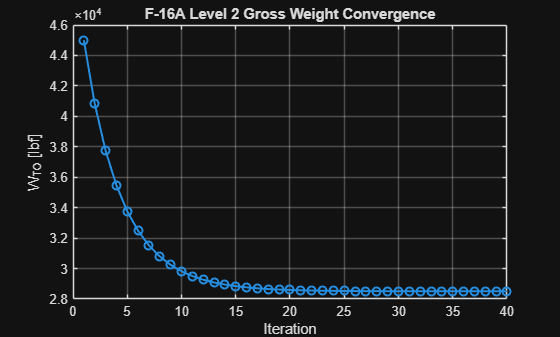

figure('Name', 'Level 2 Gross Weight Convergence');
iterationIdx = 1:height(sizing_obj.results_table);
plot(iterationIdx, sizing_obj.results_table.WTO, '-o', 'LineWidth', 1.5);grid on;
xlabel('Iteration');
ylabel('W_{TO} [lbf]');
title('F-16A Level 2 Gross Weight Convergence');

## Plot closure error

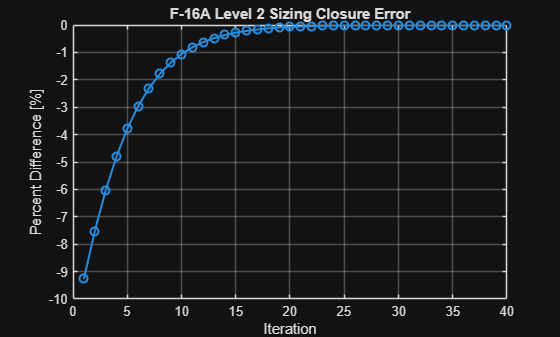

figure('Name', 'Level 2 Closure Error');
iterationIdx = 1:height(sizing_obj.results_table);
plot(iterationIdx, sizing_obj.results_table.Percent_Diff, '-o', 'LineWidth', 1.5);grid on;
xlabel('Iteration');
ylabel('Percent Difference [%]');
title('F-16A Level 2 Sizing Closure Error');

## Plot component weight breakdown

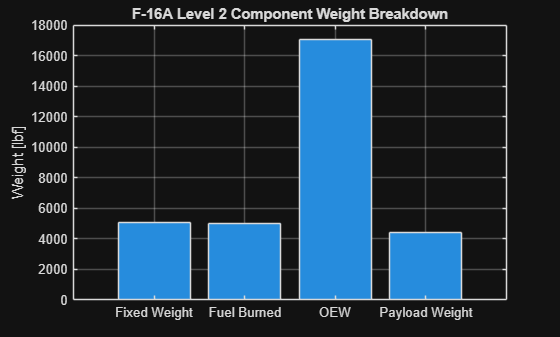

componentNames = categorical(["OEW"; "Fuel Burned"; "Fixed Weight"; "Payload Weight"]);
componentWeights_lbf = [ ...
    weight_obj.OEW; ...
    weight_obj.total_fuel_used; ...
    design.weights.Weights.Fixedlbf; ...
    mission_obj.missiondata.Combat.PayloadDroplbf];

figure('Name', 'Level 2 Component Weight Breakdown');
bar(componentNames, componentWeights_lbf);
grid on;
ylabel('Weight [lbf]');
title('F-16A Level 2 Component Weight Breakdown');

% Sources: weight_obj.OEW, weight_obj.total_fuel_used, design.weights.Weights.Fixedlbf,
% and mission_obj.missiondata.Startup.PayloadFixedlbf.

## Plot fuel burned at each mission segment

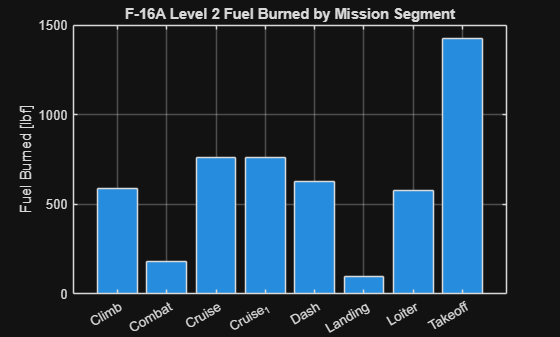

figure('Name', 'Level 2 Fuel Burned by Mission Segment');
bar(categorical(mission_obj.mission_fuel.Segment), mission_obj.mission_fuel.FuelUsed_lbf);
grid on;
ylabel('Fuel Burned [lbf]');
title('F-16A Level 2 Fuel Burned by Mission Segment');

% Source: mission_obj.mission_fuel, populated above from the existing mission object/profile.

## Plot aerodynamic coefficients at each mission segment

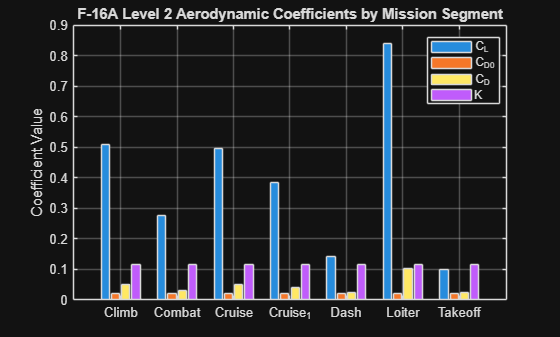

aeroMission = aero_obj.DragResults.MissionCoefficients;

figure('Name', 'Level 2 Aerodynamic Coefficients by Mission Segment');
bar(categorical(aeroMission.Segment), [aeroMission.CL, aeroMission.CD0, aeroMission.CD, aeroMission.K]);
grid on;
ylabel('Coefficient Value');
title('F-16A Level 2 Aerodynamic Coefficients by Mission Segment');
legend({'C_L', 'C_{D0}', 'C_D', 'K'}, 'Location', 'best');

% Source: aero_obj.DragResults.MissionCoefficients.

## Save results into the AircraftDesign object

AircraftDesign is a handle class, so these assignments persist on the design object during this MATLAB session.

design.WeightResults.Level2SizingTable = sizing_obj.results_table;
design.WeightResults.W_TO              = weight_obj.W_TO;
design.WeightResults.OEW               = weight_obj.OEW;
design.WeightResults.FuelUsed          = weight_obj.total_fuel_used;
design.WeightResults.FixedWeight       = design.weights.Weights.Fixedlbf;
design.WeightResults.PayloadWeight     = mission_obj.missiondata.Startup.PayloadFixedlbf;
design.WeightResults.Level2MissionFuel = mission_obj.mission_fuel;

design.AeroResults.Level2.Cf = aero_obj.Cf;
design.AeroResults.Level2.e_osw = aero_obj.e_osw;
design.AeroResults.Level2.CD0 = aero_obj.CD0;
design.AeroResults.Level2.CD = aero_obj.CD;
design.AeroResults.Level2.CL = aero_obj.CL;
design.AeroResults.Level2.K = aero_obj.K;
design.AeroResults.Level2.MissionCoefficients = aero_obj.DragResults.MissionCoefficients;

design.PropulsionResults.Level2.T0 = propulsion_obj.T0;

fprintf("\nSaved Level 2 plot/sizing data back into design.WeightResults, design.AeroResults, and design.PropulsionResults.\n");


Saved Level 2 plot/sizing data back into design.WeightResults, design.AeroResults, and design.PropulsionResults.


## Local helper functions

function assertClassOrFileExists(className)
    className = string(className);
    existsAsClass = exist(char(className), 'class') == 8;
    existsAsFile  = exist(char(className + ".m"), 'file') == 2;

    if ~(existsAsClass || existsAsFile)
        error("Required class/file '%s' was not found on the MATLAB path. Check projectRoot/addpath.", className);
    end
end

function [constraint_obj, constraintResults] = ensureConstraintResults(constraint_obj)
    needsRun = isempty(constraint_obj.optimal_WS) || isempty(constraint_obj.min_TW);

    if needsRun
        [TW_table, T_Wto_takeoff, optimal_WS, min_TW, Landing, Wto_S_landing, T0_W0, W0_S_ref, T_Wto_required] = ...
            constraint_obj.constraint_analysis();

        constraint_obj.TW_table        = TW_table;
        constraint_obj.T_Wto_takeoff   = T_Wto_takeoff;
        constraint_obj.optimal_WS      = optimal_WS;
        constraint_obj.min_TW          = min_TW;
        constraint_obj.Landing         = Landing;
        constraint_obj.Wto_S_landing   = Wto_S_landing;
        constraint_obj.T0_W0           = T0_W0;
        constraint_obj.W0_S_ref        = W0_S_ref;
        constraint_obj.T_Wto_required  = T_Wto_required;
    end

    constraintResults = table( ...
        constraint_obj.optimal_WS, ...
        constraint_obj.min_TW, ...
        constraint_obj.Wto_S_landing, ...
        'VariableNames', {'OptimalWingLoading_psf', 'MinimumThrustLoading', 'LandingWingLoadingLimit_psf'});
end

function missionSummary = summarizeMissionData(missiondata)
    segmentNames = fieldnames(missiondata);
    rows = strings(0, 1);
    mach = nan(0, 1);
    altitude = nan(0, 1);
    range = nan(0, 1);
    time = nan(0, 1);
    payloadDrop = nan(0, 1);
    cd0 = nan(0, 1);
    e = nan(0, 1);
    tsfc = nan(0, 1);

    for i = 1:numel(segmentNames)
        name = segmentNames{i};
        segment = missiondata.(name);

        rows(end+1, 1) = string(name);
        mach(end+1, 1) = getFieldOrNaN(segment, 'MachNumber');
        altitude(end+1, 1) = getFieldOrNaN(segment, 'Altitudeft');
        range(end+1, 1) = getFieldOrNaN(segment, 'Rangeft');
        time(end+1, 1) = getFieldOrNaN(segment, 'Timemin');
        payloadDrop(end+1, 1) = getFieldOrNaN(segment, 'PayloadDroplbf');
        cd0(end+1, 1) = getFieldOrNaN(segment, 'CD0');
        e(end+1, 1) = getFieldOrNaN(segment, 'e');
        tsfc(end+1, 1) = getFieldOrNaN(segment, 'TSFC');
    end

    missionSummary = table(rows, mach, altitude, range, time, payloadDrop, cd0, e, tsfc, ...
        'VariableNames', {'Segment', 'MachNumber', 'Altitude_ft', 'Range_ft', 'Time_min', 'PayloadDrop_lbf', 'CD0', 'e', 'TSFC'});
end

function value = getFieldOrNaN(s, fieldName)
    if isstruct(s) && isfield(s, fieldName)
        value = s.(fieldName);
    elseif istable(s) && any(strcmp(s.Properties.VariableNames, fieldName))
        value = s.(fieldName);
    else
        value = NaN;
    end

    if ~isscalar(value) || ~isnumeric(value)
        value = NaN;
    end
end

function [Cf, e_osw] = inferLevel2AeroInputs(mission_obj, constraint_obj, S_ref, S_wet)
    cruiseCD0 = getMissionScalar(mission_obj.missiondata, 'Cruise', 'CD0');
    cruiseE   = getMissionScalar(mission_obj.missiondata, 'Cruise', 'e');

    if ~isfinite(cruiseCD0)
        cruiseCD0 = getConstraintScalar(constraint_obj, 'Cruise', 'CD0');
    end

    if ~isfinite(cruiseE)
        cruiseE = getConstraintScalar(constraint_obj, 'Cruise', 'e');
    end

    if isfinite(cruiseCD0) && isfinite(S_ref) && isfinite(S_wet) && S_wet > 0
        Cf = cruiseCD0 * S_ref / S_wet;
    else
        Cf = 0.0035;
        warning("Could not infer Cf from mission/constraint CD0. Using Cf = %.4f.", Cf);
    end

    if isfinite(cruiseE)
        e_osw = cruiseE;
    else
        e_osw = 0.75;
        warning("Could not infer Oswald efficiency from mission/constraint data. Using e = %.3f.", e_osw);
    end
end

function value = getMissionScalar(missiondata, segmentName, fieldName)
    value = NaN;
    if isfield(missiondata, segmentName)
        value = getFieldOrNaN(missiondata.(segmentName), fieldName);
    end
end

function value = getConstraintScalar(constraint_obj, rowName, varName)
    value = NaN;
    try
        if ~isempty(constraint_obj.constraints_table) && any(strcmp(constraint_obj.constraints_table.Row, rowName))
            row = constraint_obj.constraints_table(rowName, :);
            if any(strcmp(row.Properties.VariableNames, varName))
                value = row.(varName);
            end
        end
    catch
        value = NaN;
    end

    if ~isscalar(value) || ~isnumeric(value)
        value = NaN;
    end
end

function [results_table, finalState, segmentTable] = runLevel2SizingTrace(design, geometry_obj, mission_obj, weight_obj, propulsion_obj, constraint_obj, requirements_obj, aero_obj)
    W_S = constraint_obj.optimal_WS;
    T_W = constraint_obj.min_TW;

    assert(~isempty(W_S) && isfinite(W_S), 'constraint_obj.optimal_WS must be finite.');
    assert(~isempty(T_W) && isfinite(T_W), 'constraint_obj.min_TW must be finite.');

    W_TO = weight_obj.W_TO_guess;
    W_fixed = mission_obj.missiondata.Startup.PayloadFixedlbf;

    tol = 1e-3;
    maxIteration = 40;
    rows = [];
    lastSegmentTable = table();

    for iteration = 1:maxIteration
        geometry_obj.mainwings.S_ref = W_TO / W_S;
        geometry_obj.design.S_wet = geometry_obj.get_design_S_wet(W_TO);

        propulsion_obj.T0 = T_W * W_TO;

        weight_obj.W_TO = W_TO;
        weight_obj.W_fixed = W_fixed;

        % Keep AeroLevel2 scalars synchronized with the current geometry.
        [Cf_iter, e_iter] = inferLevel2AeroInputs(mission_obj, constraint_obj, geometry_obj.mainwings.S_ref, geometry_obj.design.S_wet);
        aero_obj.Cf = Cf_iter;
        aero_obj.e_osw = e_iter;

        [fuel_used, fuel_fraction] = mission_obj.get_mission_fuel( ...
            constraint_obj, ...
            design, ...
            geometry_obj, ...
            propulsion_obj, ...
            weight_obj);

        OEW = weight_obj.get_OEW( ...
            W_TO, ...
            W_TO, ...
            geometry_obj.mainwings.AR, ...
            propulsion_obj.T0, ...
            geometry_obj.mainwings.S_ref, ...
            requirements_obj.requirements.MaxMach.Mach, ...
            weight_obj.K_vs);

        OEW_frac = OEW / W_TO;

        W_TO_new = fuel_used + W_fixed + OEW;
        difference = W_TO_new - W_TO;
        percentDifference = 100 * difference / W_TO;

        [CD0_est, K, LD_cruise] = computeLevel2AeroSnapshot( ...
            aero_obj, ...
            geometry_obj, ...
            mission_obj, ...
            W_TO, ...
            Cf_iter, ...
            e_iter);

        [TSFC_cruise, TSFC_dash, TSFC_loiter] = computeLevel2TSFCSnapshot( ...
            propulsion_obj, ...
            design, ...
            mission_obj, ...
            W_TO);

        lastSegmentTable = estimateLevel2MissionSegments( ...
            mission_obj, ...
            propulsion_obj, ...
            design, ...
            W_TO, ...
            W_S, ...
            geometry_obj.mainwings.S_ref, ...
            geometry_obj.mainwings.AR);

        rows(end+1, :) = [ ...
            iteration, ...
            W_TO, ...
            W_fixed, ...
            fuel_used, ...
            fuel_fraction, ...
            OEW_frac, ...
            OEW, ...
            geometry_obj.mainwings.S_ref, ...
            geometry_obj.design.S_wet, ...
            Cf_iter, ...
            e_iter, ...
            CD0_est, ...
            K, ...
            LD_cruise, ...
            propulsion_obj.T0, ...
            TSFC_cruise * 3600, ...
            TSFC_dash * 3600, ...
            TSFC_loiter * 3600, ...
            W_TO_new, ...
            difference, ...
            percentDifference]; %#ok<AGROW>

        if abs(difference) < tol
            W_TO = W_TO_new;
            break;
        end

        W_TO = W_TO_new;
    end

    results_table = array2table(rows, 'VariableNames', { ...
        'Iteration', ...
        'WTO_lbf', ...
        'FixedWeight_lbf', ...
        'FuelUsed_lbf', ...
        'FuelFraction', ...
        'EmptyWeightFraction', ...
        'OEW_lbf', ...
        'WingReferenceArea_ft2', ...
        'WettedArea_ft2', ...
        'Cf', ...
        'e_osw', ...
        'CD0_est', ...
        'K', ...
        'LD_cruise', ...
        'SeaLevelStaticThrust_lbf', ...
        'CruiseTSFC_per_hr', ...
        'DashTSFC_per_hr', ...
        'LoiterTSFC_per_hr', ...
        'WTO_new_lbf', ...
        'Difference_lbf', ...
        'PercentDifference'});

    last = results_table(end, :);

    finalState = struct();
    finalState.W_TO_lbf = last.WTO_new_lbf;
    finalState.W_empty_lbf = last.OEW_lbf;
    finalState.W_fixed_lbf = last.FixedWeight_lbf;
    finalState.W_fuel_lbf = last.FuelUsed_lbf;
    finalState.fuel_fraction = last.FuelFraction;
    finalState.empty_weight_fraction = last.EmptyWeightFraction;
    finalState.S_ref_ft2 = last.WingReferenceArea_ft2;
    finalState.S_wet_ft2 = last.WettedArea_ft2;
    finalState.Cf = last.Cf;
    finalState.e_osw = last.e_osw;
    finalState.CD0_est = last.CD0_est;
    finalState.K = last.K;
    finalState.LD_cruise = last.LD_cruise;
    finalState.T0_lbf = last.SeaLevelStaticThrust_lbf;
    finalState.TSFC_cruise_per_hr = last.CruiseTSFC_per_hr;
    finalState.TSFC_dash_per_hr = last.DashTSFC_per_hr;
    finalState.TSFC_loiter_per_hr = last.LoiterTSFC_per_hr;

    segmentTable = lastSegmentTable;
end

function [CD0_est, K, LD_cruise] = computeLevel2AeroSnapshot(aero_obj, geometry_obj, mission_obj, W_TO, Cf, e_osw)
    S_ref = geometry_obj.mainwings.S_ref;
    S_wet = geometry_obj.design.S_wet;
    AR = geometry_obj.mainwings.AR;

    CD0_est = aero_obj.get_design_CD0(Cf, S_wet, S_ref);
    K = 1 / (pi * AR * e_osw);

    cruise = mission_obj.missiondata.Cruise;
    q = getFieldOrNaN(cruise, 'qlbfft2');

    if isfinite(q) && q > 0
        CL = 2 * W_TO / (q * S_ref);
        CD = CD0_est + K * CL^2;
        LD_cruise = CL / CD;
    else
        LD_cruise = NaN;
    end
end

function [TSFC_cruise, TSFC_dash, TSFC_loiter] = computeLevel2TSFCSnapshot(propulsion_obj, design, mission_obj, W_TO)
    cruise = mission_obj.missiondata.Cruise;
    dash = mission_obj.missiondata.Dash;
    loiter = mission_obj.missiondata.Loiter;

    TSFC_cruise = propulsion_obj.get_TSFC_installed( ...
        design.propulsion_type, ...
        [cruise.MachNumber, cruise.Altitudeft, 0, W_TO], ...
        "mil");

    TSFC_dash = propulsion_obj.get_TSFC_installed( ...
        design.propulsion_type, ...
        [dash.MachNumber, dash.Altitudeft, 0, W_TO], ...
        "max");

    TSFC_loiter = propulsion_obj.get_TSFC_installed( ...
        design.propulsion_type, ...
        [loiter.MachNumber, loiter.Altitudeft, 0, W_TO], ...
        "mil");
end

function segmentTable = estimateLevel2MissionSegments(mission_obj, propulsion_obj, design, W_TO, W_S, S_ref, AR)
    m = mission_obj.missiondata;

    segment = strings(0, 1);
    W_in = nan(0, 1);
    W_out = nan(0, 1);
    fuel = nan(0, 1);

    W_current = W_TO;

    [W_next, f] = takeoffSegment(W_current);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Takeoff", W_current, W_next, f);
    W_current = W_next;

    [W_next, f] = climbSegment(W_current, m.Climb.MachNumber);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Climb", W_current, W_next, f);
    W_current = W_next;

    TSFC_cruise = getMissionTSFCOrInstalled(m.Cruise, propulsion_obj, design, W_current, "mil");
    [W_next, f] = breguetRangeSegment(W_current, W_TO, W_S, TSFC_cruise, m.Cruise.Rangeft, m.Cruise.MachNumber*m.Cruise.afts, m.Cruise.qlbfft2, m.Cruise.CD0, m.Cruise.e, AR);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Cruise", W_current, W_next, f);
    W_current = W_next;

    TSFC_dash = getMissionTSFCOrInstalled(m.Dash, propulsion_obj, design, W_current, "max");
    [W_next, f] = breguetRangeSegment(W_current, W_TO, W_S, TSFC_dash, m.Dash.Rangeft, m.Dash.MachNumber*m.Dash.afts, m.Dash.qlbfft2, m.Dash.CD0, m.Dash.e, AR);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Dash", W_current, W_next, f);
    W_current = W_next;

    TSFC_combat = getMissionTSFCOrInstalled(m.Combat, propulsion_obj, design, W_current, "max");
    [W_next, f] = enduranceSegment(W_current, W_TO, W_S, TSFC_combat, m.Combat.Timemin, m.Combat.qlbfft2, m.Combat.CD0, m.Combat.e, AR, m.Combat.PayloadDroplbf);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Combat", W_current, W_next, f);
    W_current = W_next;

    TSFC_cruise2 = getMissionTSFCOrInstalled(m.Cruise_1, propulsion_obj, design, W_current, "max");
    [W_next, f] = breguetRangeSegment(W_current, W_TO, W_S, TSFC_cruise2, m.Cruise_1.Rangeft, m.Cruise_1.MachNumber*m.Cruise_1.afts, m.Cruise_1.qlbfft2, m.Cruise_1.CD0, m.Cruise_1.e, AR);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Cruise_1", W_current, W_next, f);
    W_current = W_next;

    TSFC_loiter = getMissionTSFCOrInstalled(m.Loiter, propulsion_obj, design, W_current, "mil");
    [W_next, f] = enduranceSegment(W_current, W_TO, W_S, TSFC_loiter, m.Loiter.Timemin, m.Loiter.qlbfft2, m.Loiter.CD0, m.Loiter.e, AR, 0);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Loiter", W_current, W_next, f);
    W_current = W_next;

    [W_next, f] = landingSegment(W_current);
    [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, "Landing", W_current, W_next, f);

    segmentTable = table(segment, W_in, W_out, fuel, 'VariableNames', {'Segment', 'W_in_lbf', 'W_out_lbf', 'FuelUsed_lbf'});
end

function TSFC = getMissionTSFCOrInstalled(seg, propulsion_obj, design, W, powerSetting)
    TSFC = getFieldOrNaN(seg, 'TSFC');
    if ~isfinite(TSFC)
        TSFC = propulsion_obj.get_TSFC_installed( ...
            design.propulsion_type, ...
            [seg.MachNumber, seg.Altitudeft, 0, W], ...
            powerSetting);
    end
end

function LD = computeLDLevel2(W, W_TO, q, CD0, W_S, e, AR)
    W_by_WTO = W / W_TO;
    W_by_S = W_by_WTO * W_S;
    LD = 1 / ((q * CD0 / W_by_S) + (W_by_S / (q * pi * e * AR)));
end

function [W_out, fuel_used] = breguetRangeSegment(W_in, W_TO, W_S, TSFC, distance_ft, V_fts, q, CD0, e, AR)
    LD = computeLDLevel2(W_in, W_TO, q, CD0, W_S, e, AR);
    WF = exp(-((distance_ft * TSFC) / (V_fts * LD)));
    fuel_used = W_in * (1 - WF);
    W_out = W_in - fuel_used;
end

function [W_out, fuel_used] = enduranceSegment(W_in, W_TO, W_S, TSFC, time_min, q, CD0, e, AR, payloadDrop_lbf)
    LD = computeLDLevel2(W_in, W_TO, q, CD0, W_S, e, AR);
    WF = exp(-(time_min * 60 * TSFC / LD));
    fuel_used = W_in * (1 - WF);
    W_out = W_in - fuel_used - payloadDrop_lbf;
end

function [W_out, fuel_used] = climbSegment(W_in, Mach)
    WF = 1.0065 - 0.0325 * Mach;
    fuel_used = (1 - WF) * W_in;
    W_out = W_in - fuel_used;
end

function [W_out, fuel_used] = takeoffSegment(W_in)
    WF = 0.95;
    W_out = W_in * WF;
    fuel_used = W_in - W_out;
end

function [W_out, fuel_used] = landingSegment(W_in)
    WF = 0.995;
    W_out = W_in * WF;
    fuel_used = W_in - W_out;
end

function [segment, W_in, W_out, fuel] = appendSegment(segment, W_in, W_out, fuel, name, win, wout, f)
    segment(end+1, 1) = string(name);
    W_in(end+1, 1) = win;
    W_out(end+1, 1) = wout;
    fuel(end+1, 1) = f;
end

function aeroMission = computeLevel2MissionAeroCoefficients(aero_obj, geometry_obj, mission_obj, weight_obj)
    segmentNames = fieldnames(mission_obj.missiondata);

    segment = strings(0, 1);
    mach = nan(0, 1);
    altitude = nan(0, 1);
    W_in = nan(0, 1);
    CL = nan(0, 1);
    CD0 = nan(0, 1);
    CD = nan(0, 1);
    K = nan(0, 1);
    D = nan(0, 1);

    for i = 1:numel(segmentNames)
        rawName = string(segmentNames{i});
        segData = mission_obj.missiondata.(segmentNames{i});

        M = getFieldOrNaN(segData, 'MachNumber');
        h_ft = getFieldOrNaN(segData, 'Altitudeft');

        % Skip non-flight bookkeeping segments such as Startup/meta.
        if ~isfinite(M) || ~isfinite(h_ft) || M <= 0
            continue
        end

        W_seg = getSegmentInputWeight(mission_obj.mission_fuel, rawName, weight_obj.W_TO);
        state_input = [M, h_ft, 0, W_seg];

        dragResults = aero_obj.get_design_drag(geometry_obj, state_input);

        segment(end+1, 1) = rawName;
        mach(end+1, 1) = M;
        altitude(end+1, 1) = h_ft;
        W_in(end+1, 1) = W_seg;
        CL(end+1, 1) = aero_obj.CL;
        CD0(end+1, 1) = dragResults.CD0;
        CD(end+1, 1) = dragResults.CD;
        K(end+1, 1) = aero_obj.K;
        D(end+1, 1) = dragResults.D;
    end

    aeroMission = table(segment, mach, altitude, W_in, CL, CD0, CD, K, D, ...
        'VariableNames', {'Segment', 'Mach', 'Altitude_ft', 'W_in_lbf', 'CL', 'CD0', 'CD', 'K', 'Drag_lbf'});
end

function W_seg = getSegmentInputWeight(missionFuel, segmentName, defaultWeight)
    W_seg = defaultWeight;

    if istable(missionFuel) && any(strcmp(missionFuel.Properties.VariableNames, 'Segment')) && any(strcmp(missionFuel.Properties.VariableNames, 'W_in_lbf'))
        names = string(missionFuel.Segment);
        idx = find(names == segmentName, 1);

        if isempty(idx)
            idx = find(erase(names, "_") == erase(segmentName, "_"), 1);
        end

        if ~isempty(idx) && isfinite(missionFuel.W_in_lbf(idx))
            W_seg = missionFuel.W_in_lbf(idx);
        end
    end
end

